# Link to Slide Using the Target Slide Name

This example links to a slide using an `mlreportgen.ppt.InternalLink` object that specifies the target slide name.

Create the presentation.

import mlreportgen.ppt.*
ppt = Presentation("myPresentation1.pptx");
open(ppt);

Add a slide to the presentation.

slide1 = add(ppt,"Title and Content");

Choose a name to identify the target slide.

targetSlideName = "myTargetSlide";

 Create a paragraph. Create an `InternalLink` object that specifies the target slide by name and append it to the paragraph.

p = Paragraph("This is a link to the slide with the name ");
linkObj = InternalLink(targetSlideName,targetSlideName);
append(p,linkObj);

Add the title and content to the slide.

replace(slide1,"Title","First slide");
replace(slide1,"Content",p);

 Add a second slide to the presentation.

slide2 = add(ppt,"Title and Content");
replace(slide2,"Title","Second slide");

Add the target slide to the presentation. Set the `Name` property of the slide to the name specified in the `InternalLink` object.

slide3 = add(ppt,"Title and Content");
slide3.Name = targetSlideName;
replace(slide3,"Title","Third slide");
content = strcat("This is the target slide with the name ",targetSlideName);
replace(slide3,"Content",content);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here are the generated slides:

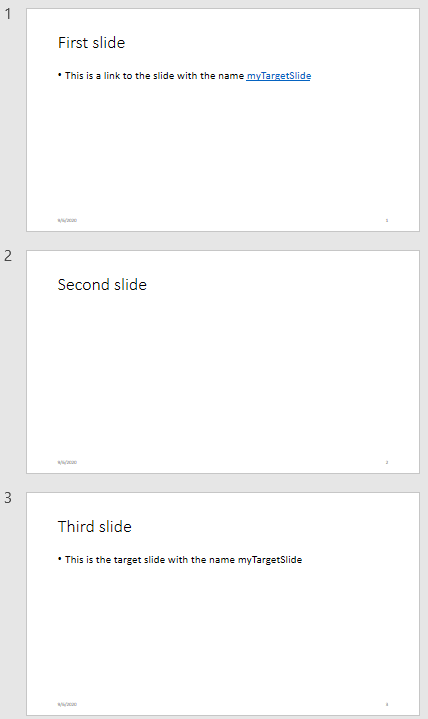

*Copyright 2020 The MathWorks, Inc.*